# Robot Navigation Project - Sequence Classification

This dataset was obtained from the UCI Machine Learning Repository. 

You can find more information on this dataset here:

[https://archive.ics.uci.edu/ml/datasets/Wall-Following+Robot+Navigation+Data](http://Wall-Following Robot Navigation Data Set)

Load the processed sensor data. This mat file contains 4 variables for the sensor data and the robot's action.

- `XTrain`: A matrix with 2 columns, one for each sensor reading. The first row is the sensor reading from the front of the robot, and the second row is the sensor reading from the left of the robot.

- `XTest`: The last 1000 time steps are reserved for testing.

- `YTrain` and `YTest`: The action the robot should take at a time step. At any point, the robot can either move forward, turn slightly to the left, turn slightly to the right, or turn sharply to the right.

load robotDataProcessed.mat

## Create architecture

Create an array of layers in the order shown below. The `bilstmLayer` should have an output mode of sequence. 100 is generally a good number of hidden units in the layer.

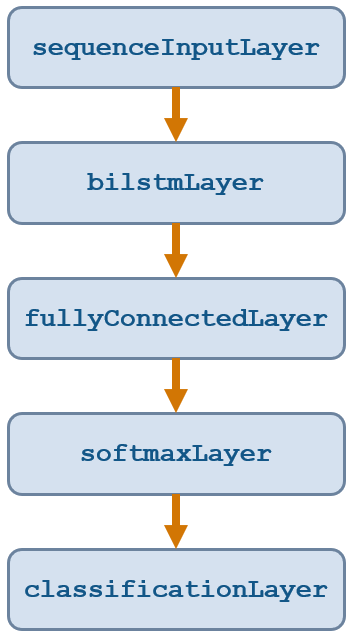

layers = [ ...
    sequenceInputLayer(2)
    bilstmLayer(100,'OutputMode','sequence')
    fullyConnectedLayer(4)
    softmaxLayer
    classificationLayer];

## Train the network

Set the training options and train the network.

options = trainingOptions('adam', ...
    'Plots','training-progress', ...
    'InitialLearnRate',0.03, ...
    'MaxEpochs',300);

Train the LSTM network.

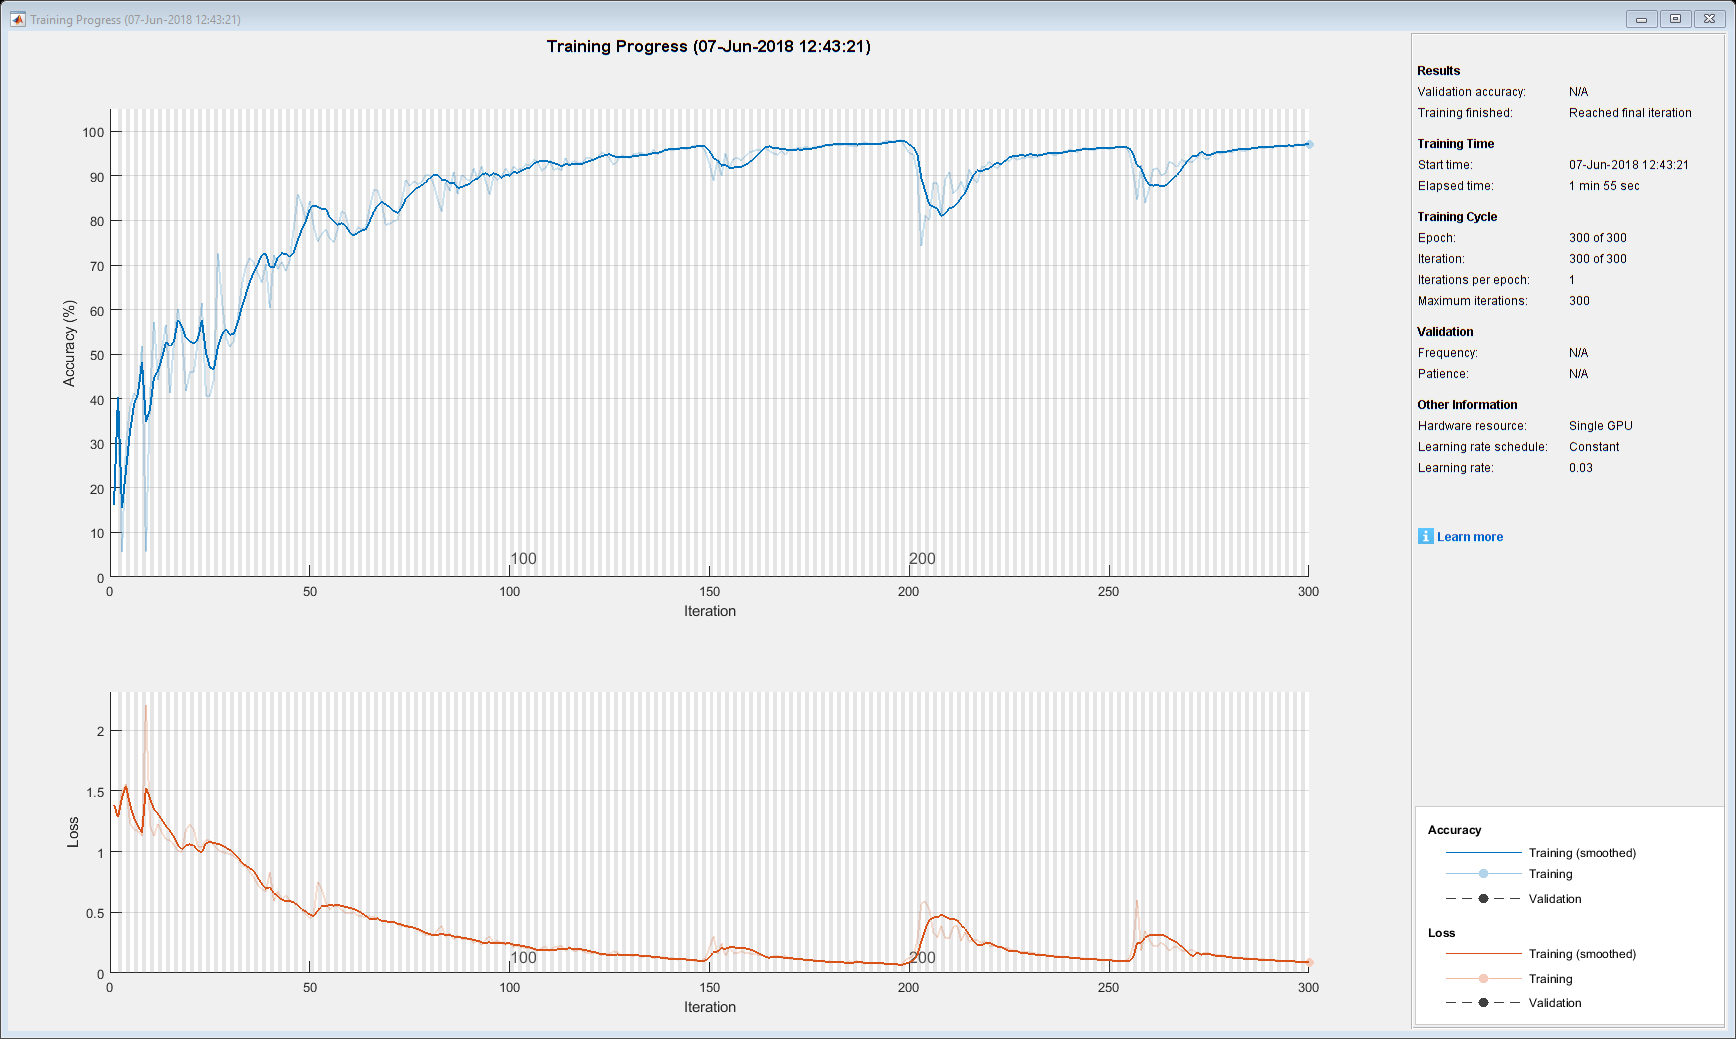

Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |       16.14% |       1.3862 |          0.0300 |
|      50 |          50 |       00:00:17 |       84.36% |       0.4481 |          0.0300 |
|     100 |         100 |       00:00:36 |       90.15% |       0.2511 |          0.0300 |
|     150 |         150 |       00:00:56 |       92.64% |       0.2106 |          0.0300 |
|     200 |         200 |       00:01:15 |       95.04% |       0.1257 |          0.0300 |
|     250 |         250 |       00:01:35 |       96.07% |       0.1055 |          0.0300 |
|     300 |         300 |       00:01:55 |       97.06% |       0.

net = trainNetwork(XTrain,YTrain,layers,options);

## Evaluate network

Calculate the accuracy on the test dataset.

testPred = classify(net,XTest);
nnz(testPred == YTest)/numel(YTest)

ans = 0.9520

Plot confusion matrix

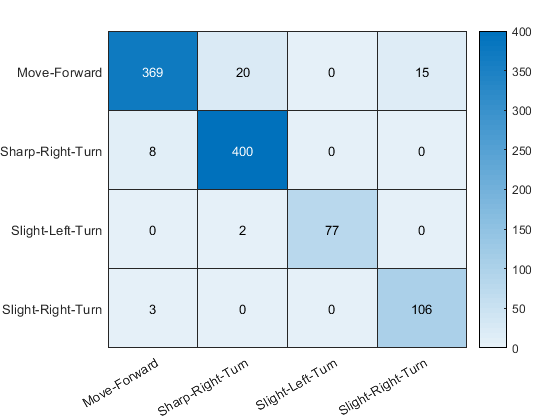

[cmap,clabel] = confusionmat(YTest,testPred);
heatmap(clabel,clabel,cmap);